# SIR Model Simulation

## Intro

The **SIR Model** has been developed to simulate an epidemic over time. The model consists of a system of 3 differential equations that express the rates of change of 3 variables over time. The 3 variables are:

1. **S** - the susceptibles of getting the infection;

2. **I** - the infected;

3. **R** - the recovered from the infection.

## The Model

Here follow the 3 equations that govern the model dynamics:


$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\frac{\beta \cdot \mathrm{S}\cdot \mathrm{I}}{N}+\alpha \cdot \mathrm{R}\\
\frac{\textrm{dI}}{\textrm{dt}}=\frac{\beta \cdot \mathrm{S}\cdot \mathrm{I}}{N}-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\alpha \cdot \mathrm{R}
\end{array}$$


## Model simulation

The following is a simulation of the model described above.

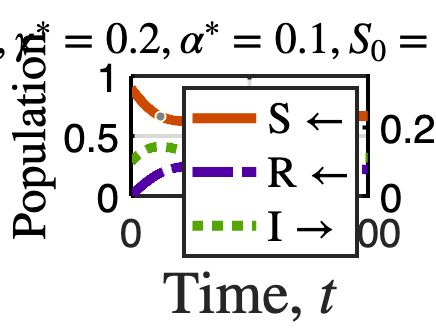

%plot setup
clf;
axes1 = axes;

hold(axes1,'on');
box(axes1,'on');
set(axes1,'FontSize',20,'LineWidth',2,'TickLength',[0.015 0.025]);
xlabel('Time, $t$','FontSize',30,'Interpreter','latex');
ylabel('Population','FontSize',24,'Interpreter','latex');
% title('$\beta=0.2$; $\gamma=0.1$','Interpreter','latex','FontSize',24);
% title('$\phi=0.5,\mu=0.1,\delta=0.05,D_{\mathrm{r}}=0.005$','Interpreter','latex','FontSize',20);


% axes1.XScale='log';
% axes1.YScale='log';

%%%% global variable for storing steady-state data
% chk=importdata("steady_vals.mat");



% Model parameters
beta = 0.3; % rate of infection
gamma = 0.2; % rate of recovery
alpha = 0.1; % rate of immunity loss
N = 1000; % Total population N = S + I + R
I0 = 0.1*N; % initial number of infected
S0 = 0.9*N;
T = 100; % period of 300 days; arbitrary units of time.
dt = 0.1; % time interval
R0=beta/gamma;
% fprintf('Value of parameter R0 is %.2f',beta/gamma)
% Calculate the model
[S,I,R] = sir_model(beta,gamma,alpha,N,S0,I0,T,dt);
% Plots that display the epidemic outbreak
tt = 0:dt:T-dt;
% Curve
% plot(tt,S./N,'b',tt,I./N,'r',tt,R./N,'g','LineWidth',2); grid on;

yyaxis left;
ylim([0. 1.]);

pl_1=plot(tt,S./N,'-');
pl_1.LineWidth=5;
pl_1.DisplayName='S$\leftarrow$';
pl_1.Color=[205./255 73./255 0.];

yyaxis right;
ylim([0. 0.35]);

pl_2=plot(tt,I./N,':');
pl_2.LineWidth=5;
pl_2.DisplayName='I$\rightarrow$';
pl_2.Color=[84./255 166./255 0.];

yyaxis left;

pl_3=plot(tt,R./N,'-.');
pl_3.LineWidth=5;
pl_3.DisplayName='R$\leftarrow$';
pl_3.Color=[82./255 0./255 166./255];


grid on;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

% xlabel('Days'); ylabel('Number of individuals');

% title(['$R_0=$',num2str(beta/gamma) '$,\,\beta=$' num2str(beta) '$,\,\gamma=$' num2str(gamma)],'Interpreter',"latex");

title(['$\beta^{*}=$' num2str(beta) '$,\,\gamma^{*}=$' num2str(gamma) '$,\,\alpha^{*}=$' num2str(alpha) '$,\,S_{0}=$' num2str(S0./N) '$,\,I_{0}=$' num2str(I0./N)],'Interpreter',"latex");


[h,icons,plots,legend_text]=legend({},'Location','east','FontSize',22,'Interpreter','latex','Box','on');



% chk=[chk; beta gamma R0 S(end)./N I(end)./N R(end)./N];
% save("steady_vals.mat","chk");

% legend('S','I','R');

% % Map
% plot(I(1:(T/dt)-1),I(2:T/dt),"LineWidth",1,"Color",'r');
% hold on; grid on;
% plot(I(2),I(1),'ob','MarkerSize',4);
% xlabel('Infected at time t'); ylabel('Infected at time t+1');
% hold off;


## What if we consider immunity loss?

In a more general model, recovered individuals could lose their immunity after some time. Let’s assume that immunity is lost, on average, after 60 days from recovery (delta = 1/60), and display the new simulation.

% delta = 1/60; % rate of immunity loss
% % Calculate the model
% [S,I,R] = sir_model(beta,gamma,delta,N,I0,T,dt);
% % Curve
% plot(tt,S,'b',tt,I,'r',tt,R,'g','LineWidth',2); grid on;
% xlabel('Days');ylabel('Number of individuals');
% legend('S','I','R');
% 

Function that calculates the model evolution over a time period T.

function [S,I,R] = sir_model(beta,gamma,alpha,N,S0,I0,T,dt)
    % if alpha = 0 we assume a model without immunity loss
    S = zeros(1,T/dt);
    S(1) = S0;
    I = zeros(1,T/dt);
    I(1) = I0;
    R = zeros(1,T/dt);
    R(1)=N-S0-I0;
    for tt = 1:(T/dt)-1
        % Equations of the model
        dS = (-beta*I(tt)*S(tt)./N + alpha*R(tt)) * dt;
        dI = (beta*I(tt)*S(tt)./N - gamma*I(tt)) * dt;
        dR = (gamma*I(tt) - alpha*R(tt)) * dt;
        S(tt+1) = S(tt) + dS;
        I(tt+1) = I(tt) + dI;
        R(tt+1) = R(tt) + dR;
    end
end
